# Pulse detector test bench (step 2)

© 2019 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

pulse_detector_reference;

Unrecognized function or variable 'pulse_detector_reference'.

## Simulate model and compare results to reference

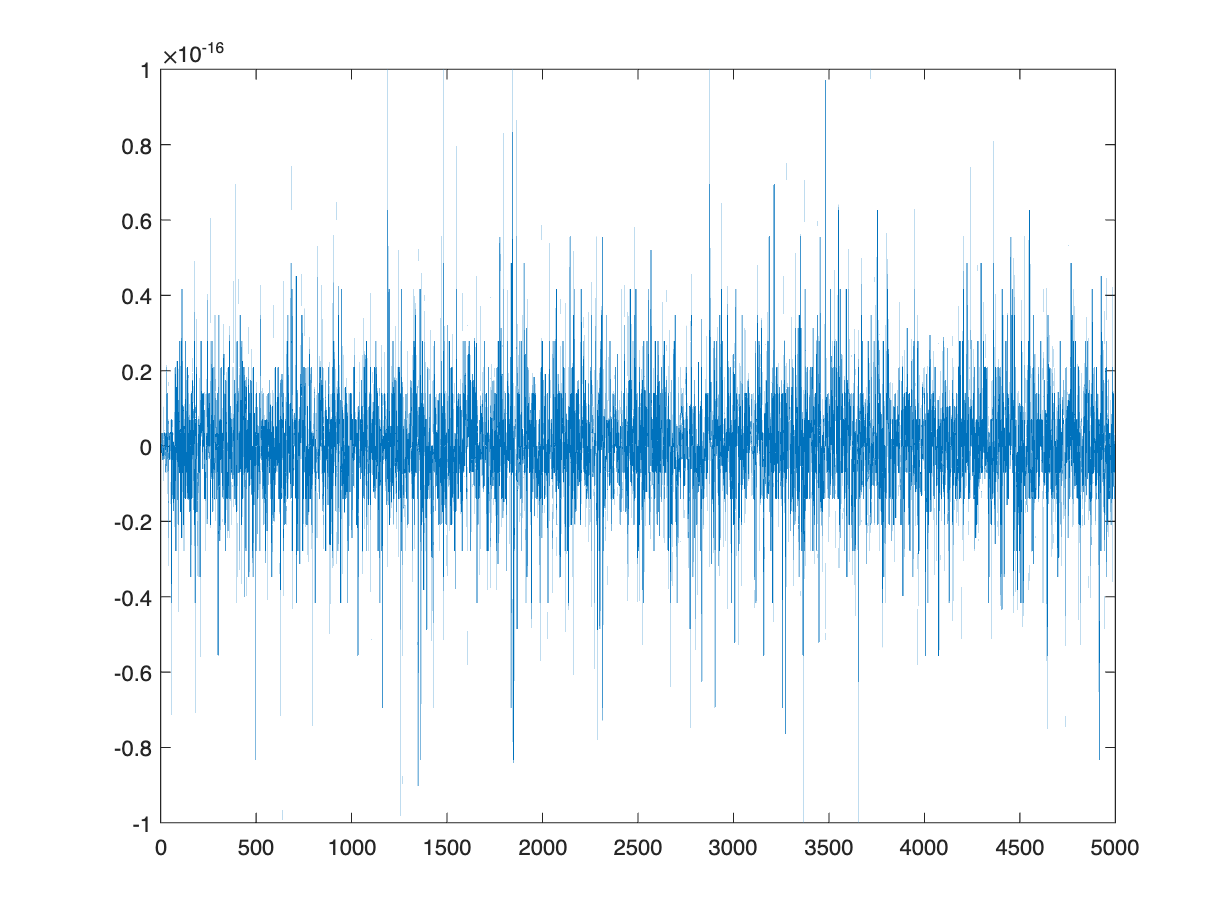

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
slout = sim('pulse_detector_v2');

% Correlation filter output
FilterOutSL = squeeze(slout.logsout.getElement('filter_out').Values.Data);
FilterValid = squeeze(slout.logsout.getElement('filter_valid').Values.Data);
FilterOutSL = FilterOutSL(FilterValid);
%compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');
%compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');
%plot(real(FilterOut)); hold on;plot(real(FilterOutSL));
plot(real(FilterOut)-real(FilterOutSL));

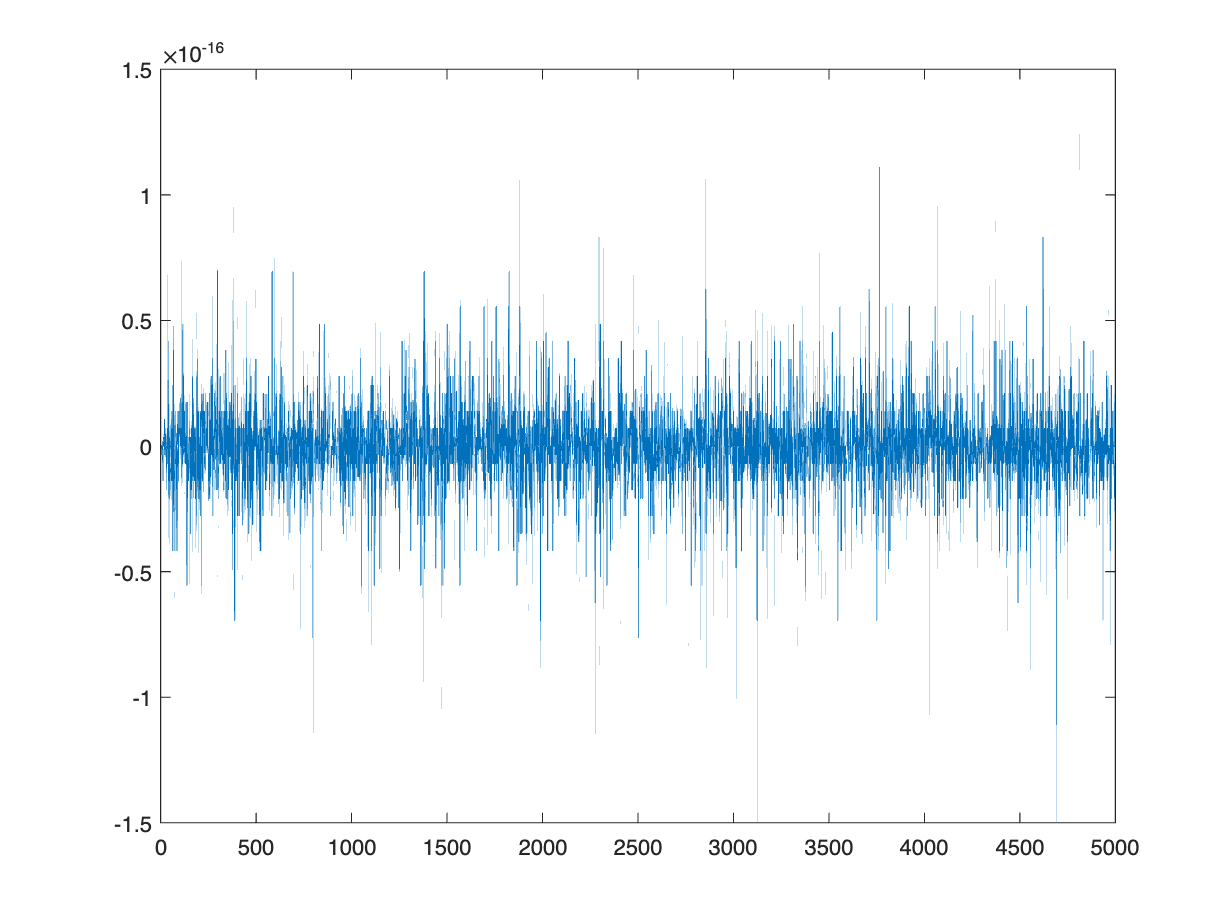

plot(imag(FilterOut)-imag(FilterOutSL));

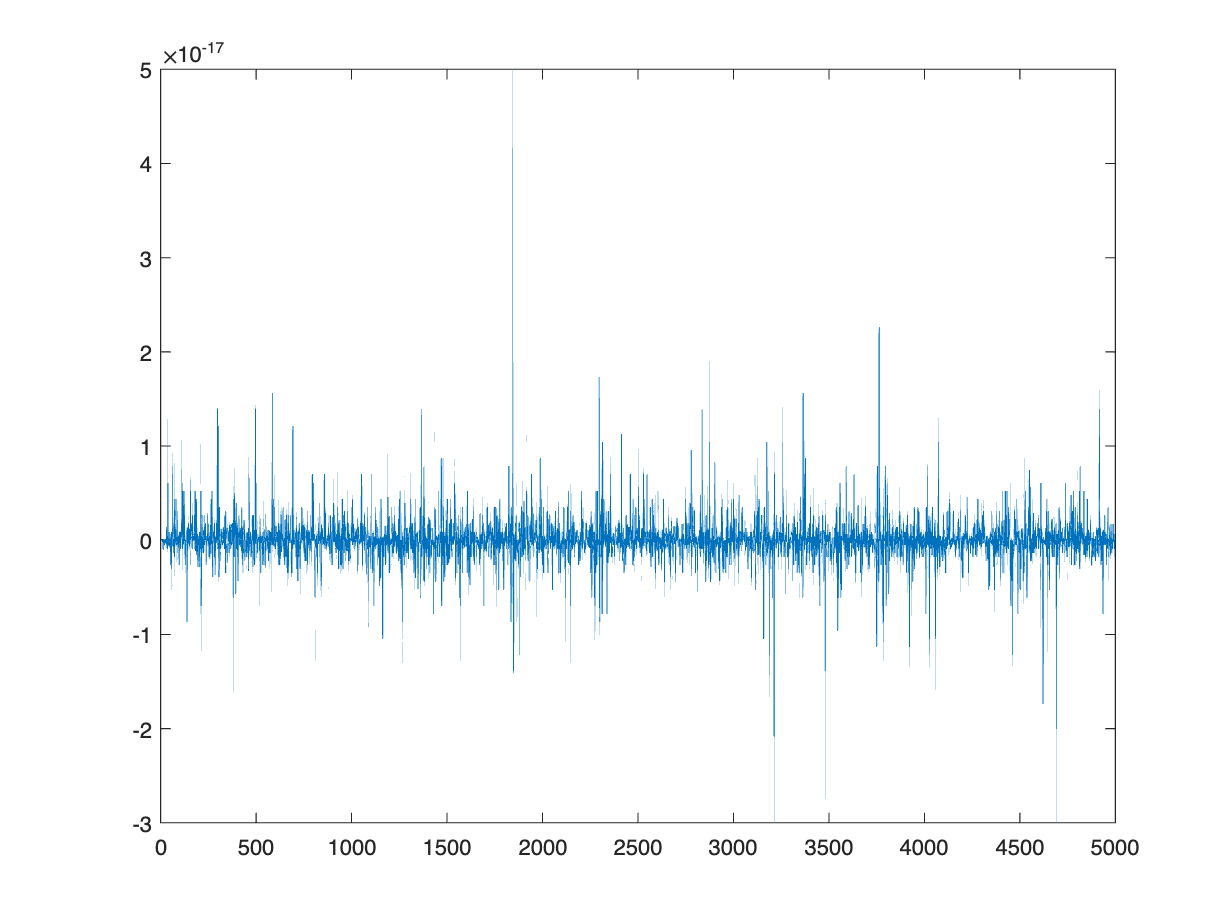


% Magnitude squared output
MagSqSL = squeeze(slout.logsout.getElement('mag_sq_out').Values.Data);
MagSqSL = MagSqSL(FilterValid);
%compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');
%plot(real(MagSqOut)); hold on;plot(real(MagSqSL));
plot(real(MagSqOut)-real(MagSqSL));


% Peak value
MidSampleSL = squeeze(slout.logsout.getElement('mid_sample').Values.Data);
Detected = squeeze(slout.logsout.getElement('detected').Values.Data);
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 1844, magnitude = 2.419e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 1844, mag-squared = 5.853e-02 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 5.853e-02, error = 4.163e-17
